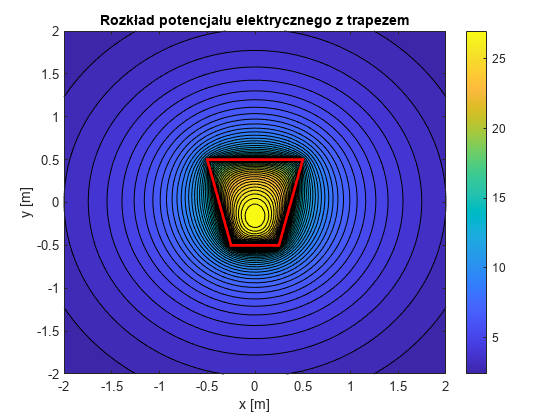


    % Parametry trapezu
    a = 0.5; % długość krótszej podstawy
    b = 1.0; % długość dłuższej podstawy
    h = 1.0; % wysokość trapezu
    sigma = 1e-9; % gęstość powierzchniowa ładunku (C/m^2)
    epsilon_0 = 8.854187817e-12; % przenikalność próżni

    % Generowanie punktów ładunków wewnątrz trapezu
    num_divisions = 100; % liczba podziałów na bok
    [x_trap, y_trap, dq] = generate_trapezoid_charge_points(a, b, h, sigma, num_divisions);

    % Definiowanie siatki obliczeniowej
    [X, Y] = meshgrid(linspace(-2, 2, 100), linspace(-2, 2, 100));
    V = zeros(size(X)); % inicjalizacja macierzy potencjału

    % Obliczenie potencjału w punktach siatki
    for i = 1:length(x_trap)
        r = sqrt((X - x_trap(i)).^2 + (Y - y_trap(i)).^2);
        r(r == 0) = 1e-10; % zapobieganie dzieleniu przez zero
        V = V + dq ./ (4 * pi * epsilon_0 * r);
    end

    % Obliczenie składowych pola elektrycznego poprzez różniczkowanie potencjału
    [Ex, Ey] = gradient(-V);

    % Rysowanie wykresu potencjału z naniesionym trapezem
    figure;
    contourf(X, Y, V, 50); hold on;
    plot_trapezoid(a, b, h);
    title('Rozkład potencjału elektrycznego z trapezem');
    xlabel('x [m]');
    ylabel('y [m]');
    colorbar;
    hold off;

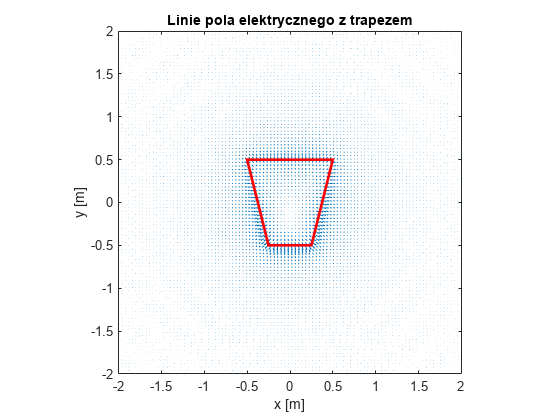


    % Rysowanie wykresu linii pola elektrycznego z naniesionym trapezem
    figure;
    quiver(X, Y, Ex, Ey); hold on;
    plot_trapezoid(a, b, h);
    title('Linie pola elektrycznego z trapezem');
    xlabel('x [m]');
    ylabel('y [m]');
    axis equal tight;
    hold off;

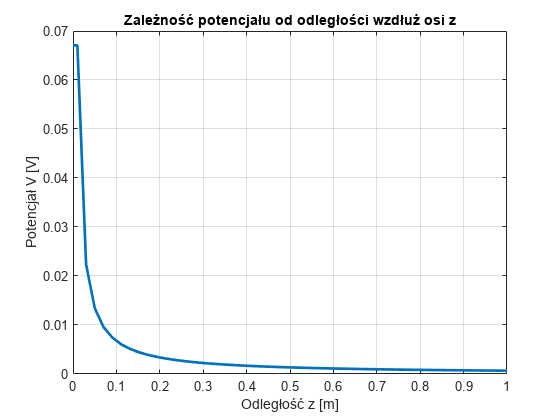

 % Obliczenie potencjału wzdłuż osi z prostopadłej do trapezu
    z_range = linspace(-2, 2, 200); % Zakres osi z
    V_along_z = zeros(size(z_range)); % Inicjalizacja potencjału wzdłuż osi z

    for i = 1:length(z_range)
        r = sqrt(z_range(i).^2);
        V_along_z(i) = sum(dq ./ (4 * pi * epsilon_0 * r));
    end

    % Rysowanie wykresu zależności potencjału od odległości r
    figure;
    plot(z_range, V_along_z, 'LineWidth', 2);
    title('Zależność potencjału od odległości wzdłuż osi z');
    xlabel('Odległość z [m]');
    ylabel('Potencjał V [V]');
    xlim([0,1])
    grid on;

function [x_trap, y_trap, dq] = generate_trapezoid_charge_points(a, b, h, sigma, num_divisions)
    % Wysokości na których będą rozmieszczone ładunki
    y_trap = linspace(-h/2, h/2, num_divisions);
    % Wyznaczenie szerokości trapezu na różnych wysokościach
    widths = linspace(a, b, num_divisions);
    % Inicjalizacja wektorów ładunków
    x_trap = [];
    y_trap_charges = [];
    % Generowanie ładunków
    for i = 1:length(y_trap)
        width = widths(i);
        x_trap_charges = linspace(-width/2, width/2, num_divisions);
        x_trap = [x_trap, x_trap_charges];
        y_trap_charges = [y_trap_charges, y_trap(i) * ones(1, num_divisions)];
    end
    y_trap = y_trap_charges;

    % Ładunek na mały element powierzchni (dq)
    total_charge = sigma * (a + b) / 2 * h; % Całkowity ładunek
    dq = total_charge / (num_divisions^2); % Ładunek na element
end

function plot_trapezoid(a, b, h)
    % Wierzchołki trapezu
    vertices = [-a/2, -h/2;
                a/2, -h/2;
                b/2,  h/2;
               -b/2,  h/2];
    % Rysowanie trapezu
    patch('Faces', [1 2 3 4], 'Vertices', vertices, 'EdgeColor', 'r', 'FaceColor', 'none', 'LineWidth', 2);
end
